%% ===============================================================
%  STEP 3 (MANUAL) - Modelo 1er orden usando escalón de 5 s
%  Archivo: analisis_bomba_step3_dinamica_manual_5s.m
%
%  Suposiciones:
%    - Cada nivel de PWM dura ~5 s.
%    - Hay un escalón grande (u0_des -> u1_des) que queremos usar.
%
%  Tú solo cambias u0_des y u1_des según tu experimento.
% ================================================================

clear; clc; close all;

%% 1) CONFIGURACIÓN
nombreArchivo   = 'datos_barrido_Com_N.csv';

% === EDITA ESTOS DOS VALORES SEGÚN TU BARRIDO ===
u0_des = 150;   % PWM antes del escalón (ej. 115)
u1_des = 155;   % PWM después del escalón (ej. 120)
% ================================================

% Duración de cada escalón según el experimento
T_step          = 5.0;   % [s]  duración total de cada nivel de PWM

% Ventana alrededor del escalón que usaremos para el modelo
T_pre_win       = 0.5;   % [s] antes del escalón (para estimar y0)
T_post_win      = 5.0;   % [s] después del escalón

% Para promediar régimen, usamos el último segundo de esos 5 s
T_regime_width  = 1.0;   % [s] ancho de ventana para régimen (último segundo)

%% 2) CARGAR DATOS
data   = readtable(nombreArchivo);
t_ms   = data.t_ms;
u_pwm  = data.PWM;
p_kPa  = data.Presion_kPa;
t_s    = t_ms / 1000.0;

Ts_prom = mean(diff(t_s));
fprintf('Ts promedio ≈ %.4f s (%.1f ms)\n', Ts_prom, Ts_prom*1000);

Ts promedio ≈ 0.0100 s (10.0 ms)



%% 3) SEGMENTAR EN TRAMOS DE PWM CONSTANTE
idxCambios = find(diff(u_pwm) ~= 0);
idxInicio  = [1; idxCambios + 1];
idxFin     = [idxCambios; length(u_pwm)];
nTramos    = numel(idxInicio);

fprintf('STEP 3 (manual): se detectaron %d tramos de PWM constante.\n', nTramos);

STEP 3 (manual): se detectaron 53 tramos de PWM constante.



%% 4) BUSCAR EL ESCALÓN ESPECÍFICO u0_des -> u1_des

escalonEncontrado = false;
k_sel = [];

for k = 1:nTramos-1
    i1 = idxInicio(k);
    i2 = idxFin(k);
    j1 = idxInicio(k+1);
    j2 = idxFin(k+1);

    pwm_before = u_pwm(i1);
    pwm_after  = u_pwm(j1);

    % Coincidencia exacta con el escalón que queremos
    if pwm_before == u0_des && pwm_after == u1_des
        % Comprobar que el tramo después dura al menos ~5 s
        if (t_s(j2) - t_s(j1)) >= (T_step - Ts_prom)
            escalonEncontrado = true;
            k_sel = k;
            break;
        end
    end
end

if ~escalonEncontrado
    error('No se encontró el escalón %g -> %g con duración ≈ %.1f s.', ...
          u0_des, u1_des, T_step);
end

fprintf('Escalón seleccionado: %g -> %g (tramo %d -> %d)\n', ...
        u0_des, u1_des, k_sel, k_sel+1);

Escalón seleccionado: 150 -> 155 (tramo 31 -> 32)



%% 5) OBTENER DATOS DEL ESCALÓN SELECCIONADO

% Tramo antes y después
i1 = idxInicio(k_sel);
i2 = idxFin(k_sel);
j1 = idxInicio(k_sel+1);
j2 = idxFin(k_sel+1);

u0 = u_pwm(i1);
u1 = u_pwm(j1);

t_before_full = t_s(i1:i2);
p_before_full = p_kPa(i1:i2);

t_after_full  = t_s(j1:j2);
p_after_full  = p_kPa(j1:j2);

% Instante de escalón
t_step = t_s(j1);
fprintf('Instante de escalón t_step = %.3f s\n', t_step);

Instante de escalón t_step = 157.010 s



%% 6) DEFINIR VENTANA ALREDEDOR DEL ESCALÓN

t_ini_win = t_step - T_pre_win;
t_fin_win = t_step + T_post_win;

idx_window = find( t_s >= t_ini_win & t_s <= t_fin_win );

t_win = t_s(idx_window);
u_win = u_pwm(idx_window);
p_win = p_kPa(idx_window);

% Separar antes y después dentro de esa ventana
idx_before = find(t_win < t_step);
idx_after  = find(t_win >= t_step);

t_before = t_win(idx_before);
p_before = p_win(idx_before);

t_after  = t_win(idx_after);
p_after  = p_win(idx_after);

%% 7) CÁLCULO DE y0 (nivel inicial)

if isempty(t_before)
    error('La ventana T_pre_win es muy pequeña, no hay datos antes del escalón.');
end

t_ini_y0 = t_step - T_pre_win;
idx_y0   = find( t_before >= t_ini_y0 );
if isempty(idx_y0)
    idx_y0 = 1:numel(t_before);
end
y0 = mean( p_before(idx_y0) );

%% 8) CÁLCULO DE y_inf (régimen al final de los 5 s)

t_ini_reg = t_step + (T_post_win - T_regime_width);
t_fin_reg = t_step + T_post_win;

idx_regime = find( t_after >= t_ini_reg & t_after <= t_fin_reg );
if isempty(idx_regime)
    warning('No se encontraron muestras en la ventana de régimen; usando últimas disponibles.');
    idx_regime = max(1, numel(t_after)-5) : numel(t_after);
end

y_inf = mean( p_after(idx_regime) );

%% 9) GANANCIA ESTÁTICA K

du = (u1 - u0);
dy = (y_inf - y0);
K  = dy / du;

%% 10) CÁLCULO DE TAU (63.2%) DENTRO DE LA VENTANA

t_resp = t_after;
y_resp = p_after;

frac = 1 - exp(-1);      % ≈ 0.632
y_target = y0 + frac * dy;

idxTau = [];

if dy > 0
    idxTau = find(y_resp >= y_target, 1, 'first');
elseif dy < 0
    idxTau = find(y_resp <= y_target, 1, 'first');
end

if isempty(idxTau)
    warning('No se encontró cruce al 63.2%% dentro de la ventana; tau no confiable.');
    tau = NaN;
else
    t_tau_abs = t_resp(idxTau);
    tau = t_tau_abs - t_step;
end

%% 11) RESULTADOS EN CONSOLA

fprintf('--- RESULTADOS (escalón manual de 5 s) ---\n');

--- RESULTADOS (escalón manual de 5 s) ---


fprintf('u0       = %.1f PWM\n', u0);

u0       = 150.0 PWM


fprintf('u1       = %.1f PWM\n', u1);

u1       = 155.0 PWM


fprintf('y0       = %.3f kPa\n', y0);

y0       = -33.982 kPa


fprintf('y_inf    = %.3f kPa\n', y_inf);

y_inf    = -34.055 kPa


fprintf('Δu       = %.1f PWM\n', du);

Δu       = 5.0 PWM


fprintf('Δy       = %.3f kPa\n', dy);

Δy       = -0.073 kPa


fprintf('K        = %.4f kPa/PWM\n', K);

K        = -0.0145 kPa/PWM


fprintf('tau      = %.4f s (%.1f ms)\n', tau, tau*1000);

tau      = 0.0600 s (60.0 ms)


fprintf('Modelo propuesto:  G(s) = %.4f / (%.4f s + 1)\n', K, tau);

Modelo propuesto:  G(s) = -0.0145 / (0.0600 s + 1)


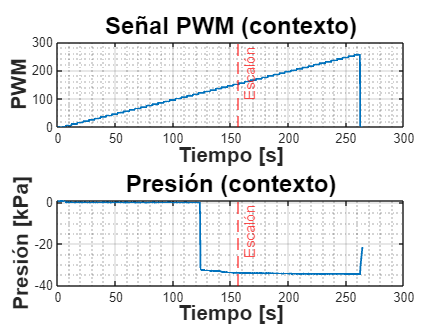


%% 12) GRÁFICAS

LW   = 2.0;
FS   = 14;
FSbig = 16;
morado = [0.4 0 0.8];

% --- 12.1 Contexto global ---
figure('Name','Contexto del escalon','Color','w');

subplot(2,1,1);
plot(t_s, u_pwm, 'LineWidth', 1.2); hold on;
xline(t_step, '--r', 'Escalón');
grid on; grid minor;
xlabel('Tiempo [s]', 'FontSize', FS, 'FontWeight','bold');
ylabel('PWM', 'FontSize', FS, 'FontWeight','bold');
title('Señal PWM (contexto)', 'FontSize', FSbig, 'FontWeight','bold');

subplot(2,1,2);
plot(t_s, p_kPa, 'LineWidth', 1.2); hold on;
xline(t_step, '--r', 'Escalón');
grid on; grid minor;
xlabel('Tiempo [s]', 'FontSize', FS, 'FontWeight','bold');
ylabel('Presión [kPa]', 'FontSize', FS, 'FontWeight','bold');
title('Presión (contexto)', 'FontSize', FSbig, 'FontWeight','bold');

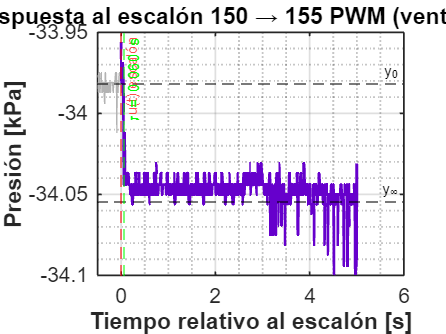


% --- 12.2 Respuesta en la ventana ---
figure('Name','Respuesta al escalon (5s)','Color','w');

t_rel_before = t_before - t_step;
t_rel_after  = t_after  - t_step;

plot(t_rel_before, p_before, 'LineWidth', 1.0, 'Color', [0.7 0.7 0.7]); hold on;
plot(t_rel_after,  p_after,  'LineWidth', LW, 'Color', morado);

yline(y0,   '--k', 'y_0');
yline(y_inf,'--k', 'y_{\infty}');
xline(0,    '--r', 'u(t) escalón');

if ~isnan(tau)
    xline(tau, '--g', sprintf('\\tau = %.3f s', tau));
end

grid on; grid minor;
xlabel('Tiempo relativo al escalón [s]', 'FontSize', FS, 'FontWeight','bold');
ylabel('Presión [kPa]', 'FontSize', FS, 'FontWeight','bold');
title(sprintf('Respuesta al escalón %g → %g PWM (ventana 5 s)', u0_des, u1_des), ...
      'FontSize', FSbig, 'FontWeight','bold');

ax = gca;
ax.FontSize = FS;
ax.LineWidth = 1.2;

ax.Box = 'on';
